# Lab 1 Exercises 

## 1. Setup 

    1.1 Start Matlab 

    1.2 Download and install Peter Corke’s modified robotics toolbox (See UTSOnline) 

    1.3 Run the demos (type “rtbdemo”) to show the arms and get an idea what is possible.

## 2. Consider a car driving around a circular track

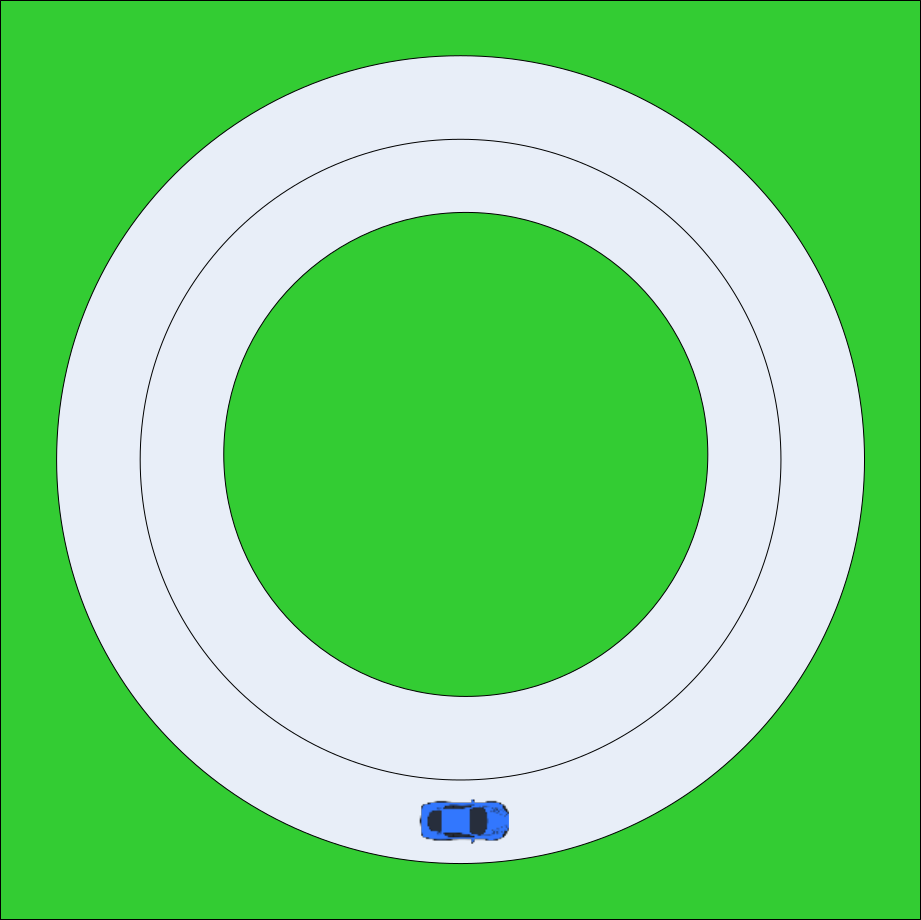

    2.1 Download the image from UTSOnline to file “W1LabEx1_CircularRaceTrack.jpg”, then open Matlab and Load the image with: 

cd ~/MATLAB-Drive/41013_Robotics/Week_1/
imshow('W1LabEx1_CircularRaceTrack.jpg');
axis on;

    2.2 Plot a transform representing the car at [300,550], use the ‘X’ axis of the transform to represent the heading of the car (note you will need to use “hold on” to show both)

hold on
Tr = se2(300,550,0)

Tr =      1     0   300
     0     1   550
     0     0     1


    2.3 Make the leg lengths of the transform 50 units long so it is visible on the track.

Tr_h = trplot2(t,'frame','1','color','b','length',50)

Tr_h =   Transform with properties:

    Children: [5×1 Graphics]
     Visible: 'on'
     HitTest: 'on'
      Matrix: [4×4 double]

  Show all properties


    2.4 Now incrementally multiply the transform of the car by an offset transform and update the transform of the car

forloopincrements = 360;

Move_Tr = se2((pi * 484)/forloopincrements, 0, 0);
Turn_Tr = se2(0, 0, -2*pi/forloopincrements);

for(i=1:forloopincrements)
    Tr = Tr * Move_Tr * Turn_Tr;
    try delete(Tr_h);end
    Tr_h = trplot2(t,'frame','1','color','b','length',50);
    drawnow();
end

    2.5 Display the transform of the car using the Matlab “text” command e.g. 

message = sprintf('Line #1\nThe second line.\nAnd finally a third line.') 

message =     'Line #1
     The second line.
     And finally a third line.'


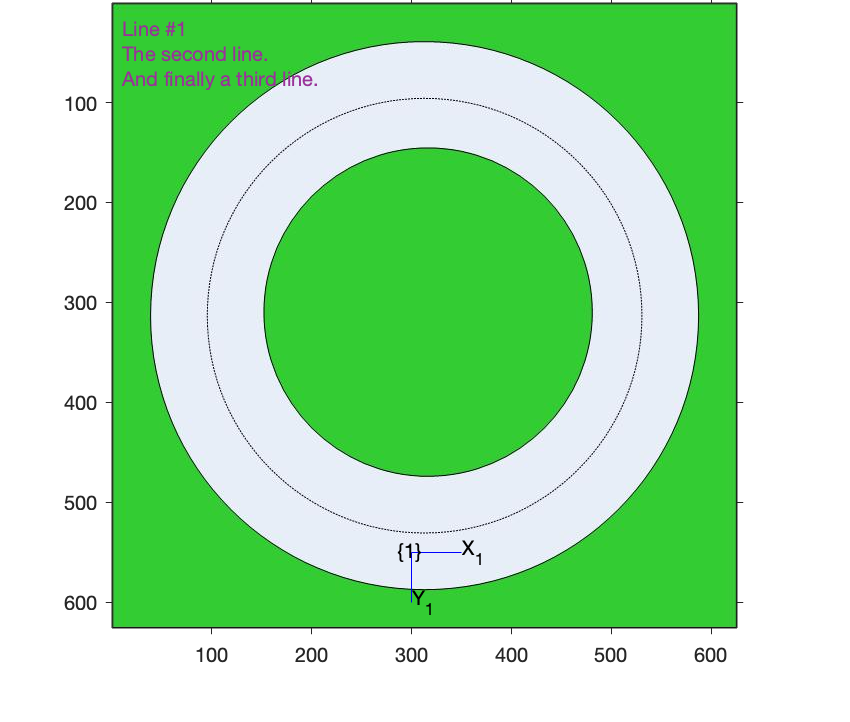

text(10, 50, message, 'FontSize', 10, 'Color', [.6 .2 .6]);

## 3. Consider a second car driving in the opposite direction

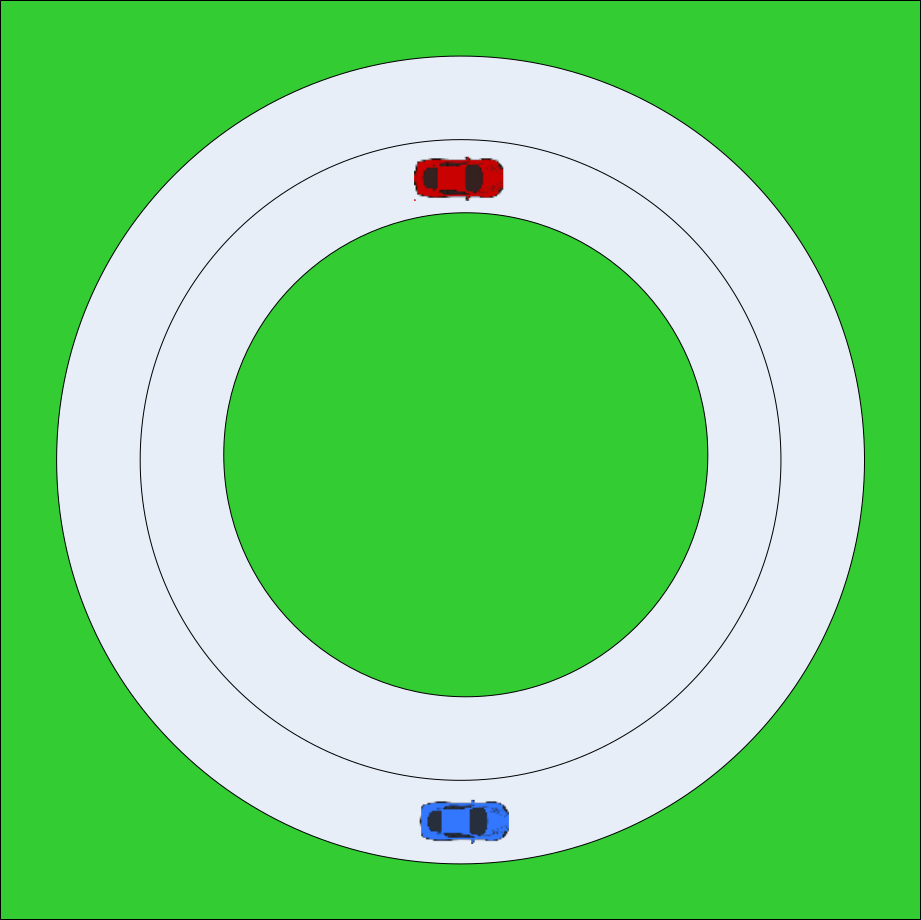

    3.1 Plot a transform representing the second car at [300,125], use the ‘X’ axis of the transform to represent the heading of the car, make transform red with length of 50. 

    3.2 Make the second car incrementally drives in the opposite direction to the first car 

    3.3 Determine the relative transform between the two cars at each time step 

## 4. Bonus: Consider a distance sensor mounted to the first car (blue) that is tracking the distance to the second car 

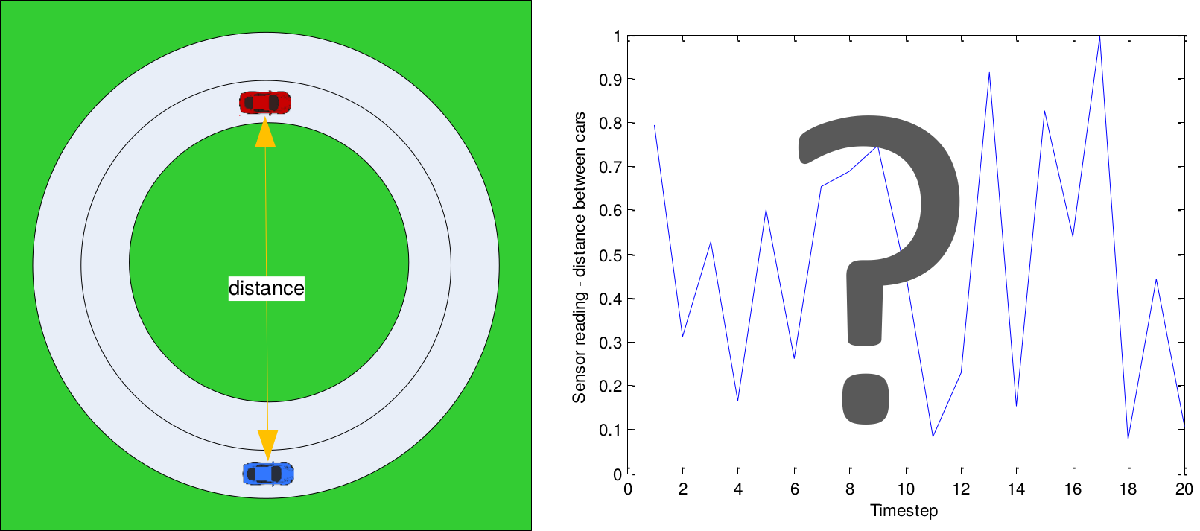

    4.1 Plot a graph of the distances between the two cars as they drive around the track